# Part 3: Comparative Genetics

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

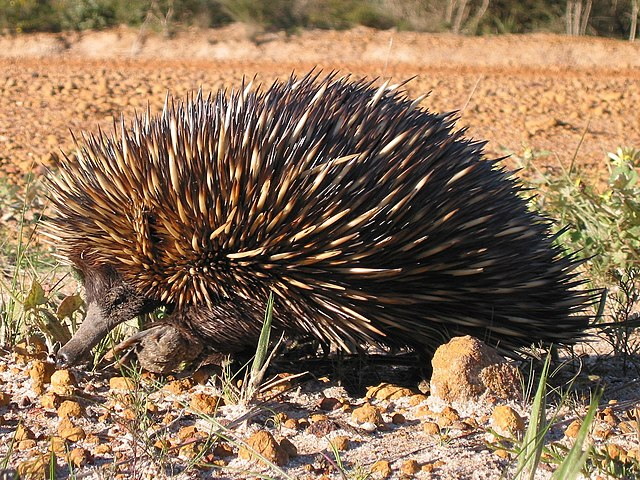

An [echidna](https://commons.wikimedia.org/wiki/File:Echidna_burningwell.jpg), perhaps looking for a snack. 

In this section, we will compare the mtDNA sequence of our friend the platypus to the mtDNA sequences of other species! You should go through the prior section on exploring a single DNA sequence first. If the platypus DNA sequence is no longer in your Workspace, this line of code will add it so you're set up for this section: 

platypus = getgenbank("NC_000891", "sequenceonly", true);

## 1: Calculate the genetic distance between platypus and echidna

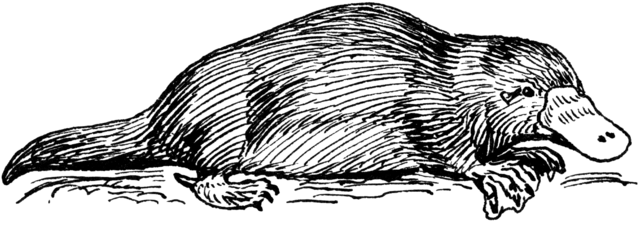            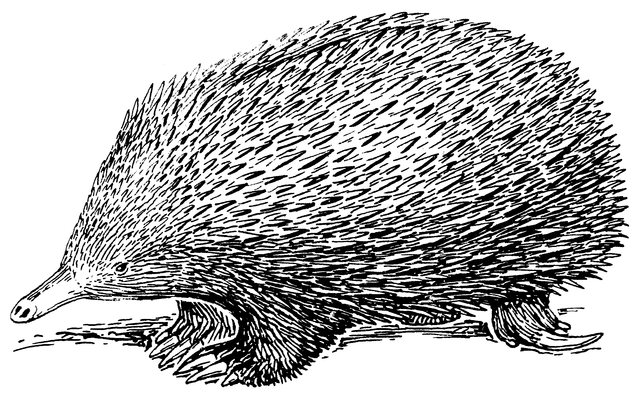

[Platypus](https://commons.wikimedia.org/wiki/File:Platypus_2_(PSF).png) vs. [Echidna](https://commons.wikimedia.org/wiki/File:Echidna_(PSF).png) 

The platypus is known to be [relatively evolutionarily close to the echidna](https://www.nature.com/articles/s41586-020-03039-0) -- both of them are egg-laying mammals, which is super rare! There are only 5 known species of mammals that lay eggs rather than have live births (called 'monotremes'), and four of these are different species of echidnas. Monotremes are considered to be evolutionarily primitive because they are mammals, but still share several traits with reptiles (e.g. laying eggs). 

We can calculate the ['genetic distance](https://bio.libretexts.org/Bookshelves/Introductory_and_General_Biology/Book:_General_Biology_(Boundless)/13:_Modern_Understandings_of_Inheritance/13.01:_Chromosomal_Theory_and_Genetic_Linkage/13.1B:_Genetic_Linkage_and_Distances)' between these two species, which is a measure of how similar the DNA of these two species is. Here we will assume that mutations are happening at a constant rate and that DNA mutates one nucleotide at a time. 

We already have the mtDNA sequence for the platypus, let's grab the mtDNA sequence for its friend the short-beaked echidna:

echidna = getgenbank("NC_003321", "sequenceonly", true);

Now we can use the Bioinformatics Toolbox™ function [`seqpdist()`](https://www.mathworks.com/help/bioinfo/ref/seqpdist.html) to calculate the genetic distance between these two species. `seqpdist` calculates the pairwise distance between sequences.  The default method that MATLAB® uses to calculate these distances is `'Jukes-Cantor'`. This [model](https://en.wikipedia.org/wiki/Models_of_DNA_evolution) assumes that all nucleotide changes happen at an equal rate and can happen in reverse. The frequency of mutation remains constant over time. This is a simplified model but is good in basic analyses. More complex models can be specified just use 

to see your options. 

  Try typing `help seqpdist`: 

We're just going to use the default model here! It is easiest to give the `seqpdist()` function a structure that contains a `Sequence` field. The function can automatically take this in and knows it is a genetic sequence. Let's first set up a structure called `seqs` which has a `Sequence` field with our platypus and echidna sequences. It's good practice to also add a `Header` field with the names of your species (it could get confusing to keep track once you have any more than 2!)

seqs(1).Sequence = platypus; 
seqs(2).Sequence = echidna; 

seqs

Here, we've made a little structure with a "SEQUENCE" field-- `seqs(1).Sequence` is the platypus mtDNA sequence

Add your headers! 

Single quotations like 'hello' indicate a [character vector](https://www.mathworks.com/help/matlab/characters-and-strings.html), while double quotations like "hello" indicate a string array. Most of the time, we use string arrays for text. In this case, we need to use character vectors, because we are going to use a particular function later (`phylotree`) that requires character vectors as input. All this to say-- we're going to use single quotations for our headers here: 

seqs(1).Header = 'Platypus';

  Add the echidna header by running 

in the cell block below: 

Let's check out what `seqs` looks like now: 

seqs

Note that these sequences are not necessarily automatically aligned, but `seqpdist` aligns them automatically before calculating distance. Go to [this MATLAB reference](https://www.mathworks.com/help/bioinfo/sequence-alignment.html?s_tid=CRUX_topnav) to learn more about sequence alignment.

Beautiful! Let's calculate the distance between these two sequences:

distSeq = seqpdist(seqs)

Calculation of the genetic distance is a bit complicated, but in general, the smaller the genetic distance number, the less divergent the two species are. These numbers are most often used in comparison to distances between other species. So let's try that and calculate the distance between the echidna and a human of European ancestry. We can assume that the human is further away genetically from the echidna than the platypus, so let's see what that looks like. 

## 2: Calculate the genetic distance between echidna and (European) human

                 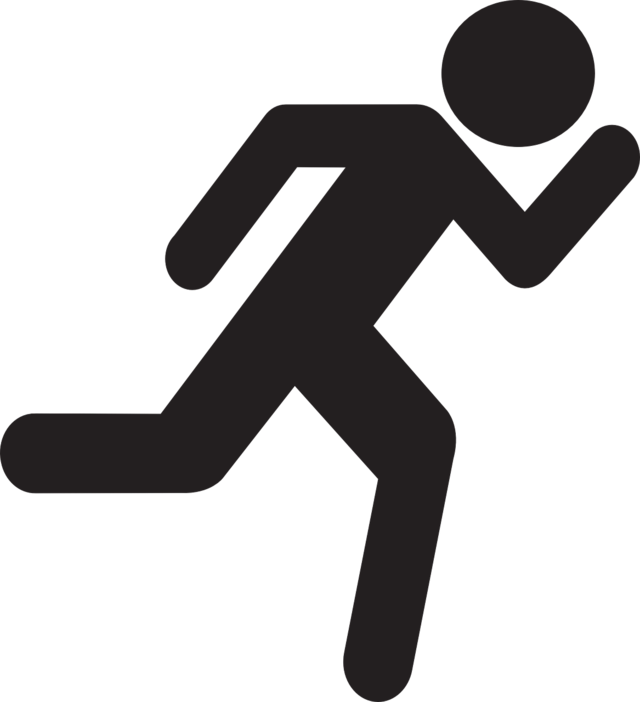

Platypus vs. [Human](https://commons.wikimedia.org/wiki/File:Runner_stickman.png) (this will be an interesting battle!)

Pull the European human reference mtDNA.

humanEuro = getgenbank("X90314", "sequenceonly", true); 

seqs(3).Sequence = humanEuro; 
seqs(3).Header = 'Human (european)'

Ok now let's compare the echidna and human: 

distanceEH = seqpdist(seqs(2:3))

 Compare this distance to the distance we found between the echidna and platypus. What does that tell you? 

The human-platypus distance is a *much* bigger genetic distance than that of the echidna-platypus comparison. This tells us we broke away from the platypus pretty far back in evolutionary history. 

We can now compare all 3 to each other. So we have three species to compare and we need to find: (1) the genetic distance of platypus- echidna, (2) platypus-human, and (3) echidna- human (3), so  `seqpdist `will give us three distances. Note that they will be printed out in the same order that I've written here! 

distAll = seqpdist(seqs) 

If you have 4 species to compare, you'd end up with 6 distance measurements from `seqpdist`: 1-2, 1-3, 1-4, 2-3, 2-4, and 3-5. Again, this is the correct order. The number of distance measurements you'll have given several species follows the standard formula for [combinations without repetition.](https://en.wikipedia.org/wiki/Combination) 

## 3: Make a phylogenetic tree 

There's a function we can use to convert this distance data into a little tree, which is very fun. This is called a [phylogenetic tree](https://en.wikipedia.org/wiki/Phylogenetic_tree), and it shows the evolutionary relationships among species based on their genetic characteristics (in this case how similar/different their genome is based on the number of mutations, which we've been calling 'genetic distance'). It's just a way to map out our distance results visually. 

[`seqlinkage`](https://www.mathworks.com/help/bioinfo/ref/seqlinkage.html) takes the distances as input and constructs a tree object! You also need to specify the distance method used for plotting. "single" is the most straightforward, but there are multiple to try out! Finally, specify where the distance data was calculated from (`seqs`) so that the function can use the header names to make the tree readable! 

phylotree = seqlinkage(distAll, "single", seqs); 

Now we have a phylogenetic tree object. Let's plot it! 

plot(phylotree) 

You can see visually that platypus and echidna are pretty close genetically, but humans diverged a long time ago. 

###  Exercise: Compare genetic sequences from multiple mammals

Next, it's time to try making a phylogenetic tree for more mammals. 

First, let's pull the data from [GenBank](https://www.ncbi.nlm.nih.gov/genbank/)! 

Here, we set up a [cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) that contains the name and GenBank accession number of a number of interesting mammals: 

mammalsimport = {'Platypus'          "NC_000891";
                 'Echidna'           "NC_003321";
                 'African Elephant'  "NC_000934"; 
                 'Polar bear'        "NC_003428"; 
                 'Cape Golden Mole'  "NC_004920"; 
                 'Domestic cat'      "NC_001700"; 
                 }; 

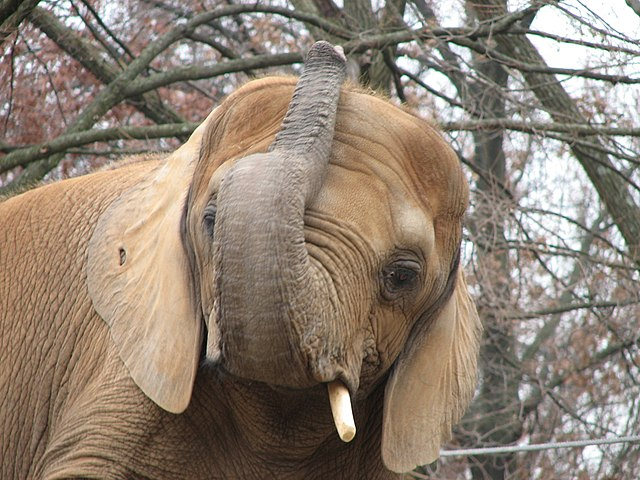     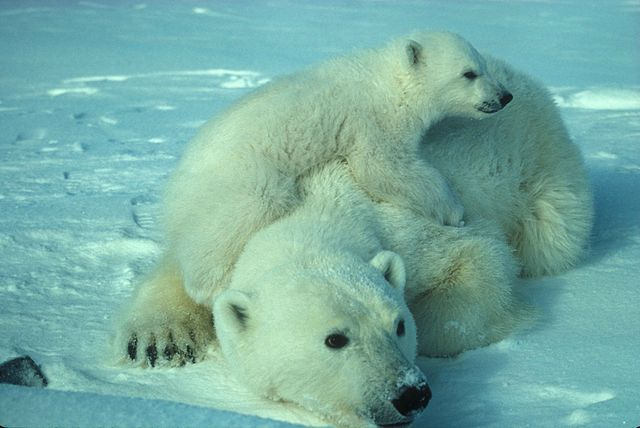     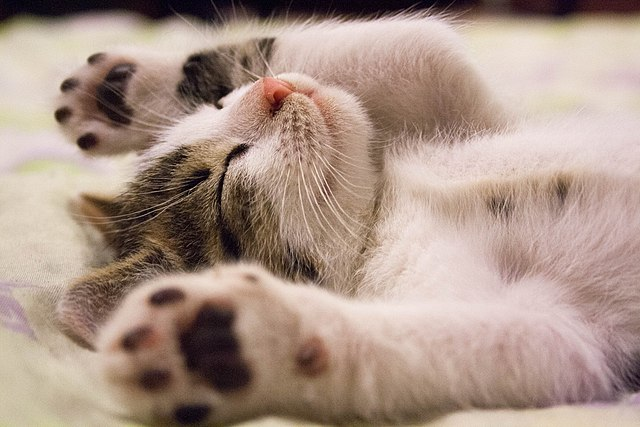

An [African elephant](https://commons.wikimedia.org/wiki/File:African_Elephant_001.jpg), a [polar bear](https://commons.wikimedia.org/wiki/File:Polar_bear_with_cub.jpg) (and her cub!), and a sleepy [kitten](https://commons.wikimedia.org/wiki/File:Kitten_sleeping.jpg) 

Now, we'll use a ***for loop*** as we did in [part 2](matlab: edit S2_Single_seq.mlx) of this module. In the first iteration of the loop, i=1, so `mammals(1).Header` will be equal to `mammalsimport{1,1}`, which is the value 'Platypus'. Perfect!` mammals(1).Sequence` is equal to `getgenbank('NC_000891', 'SequenceOnly', 'true')`, and this pulls the reference mtDNA sequence from GenBank for the platypus. Each iteration of the loop will pull data from `mammalsimport` in this way. Run this section (note that this might take a few seconds to run!) and then check out what `mammals` looks like: 

for i = 1: length(mammalsimport) %discuss how you can set up a nice structure with your headers and the dna 
    mammals(i).Header = mammalsimport{i,1};
    mammals(i).Sequence = getgenbank(mammalsimport{i,2}, "SequenceOnly",true);
end 

mammals

Now we have a structure of our sequences called `mammals`. Let's calculate the distance! This procedure is the same as we did for `seqs,` so you should try it out for yourself! 

  Calculate the genetic distances between the 6 species of `mammals` using `seqpdist`. Name your variable `distances`. Don't worry if this line of code takes a little while to run-- what we're doing here is computationally intensive and will take about 35 seconds to execute. 

  Construct a phylogenetic tree using `seqlinkage`. Use your variable `distances` and the 'single' distance method. Name your tree object `mammalTree`.

  Plot `mammalTree`: 

 Which animals are most evolutionarily close?

 It's interesting to note that the way this tree breaks down is along the lines of how these species are considered taxonomically. We know the platypus and echidna are monotremes, which is an 'order' in taxonomic ranking. The cat and polar bear are [Carnivorans](https://en.wikipedia.org/wiki/Carnivora), an order of mammals that primarily eat other animals. The elephant and mole are [Afrotherains](https://en.wikipedia.org/wiki/Afrotheria), a group of mammals whose evolutionary tree begins in Africa. You can make much more complex phylogenic trees that break down along less coarse taxonomic lines! In the problem set at the end of this module, you'll make a finer phylogenetic tree of the Hominidae family, which contains 4 genera and includes chimpanzees and humans! 

###  Exercise sample code: 

distances = seqpdist(mammals); 

mammalTree = seqlinkage(distances, "single", mammals); 

plot(mammalTree) 

[*Go to next section (Population genetics)*](matlab: edit S4_Population_genetics.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)